# Actividad 1.12 (Modelado Cinemático de Piernas)

Alan Iván Flores Juárez | A01736001

Se obtienen la matriz de transformación homogénea de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo. Para esto se realizan rotaciones y traslaciones necesarias para cada uno de los estados de configuración del robot.

## **Primer ejercicio**

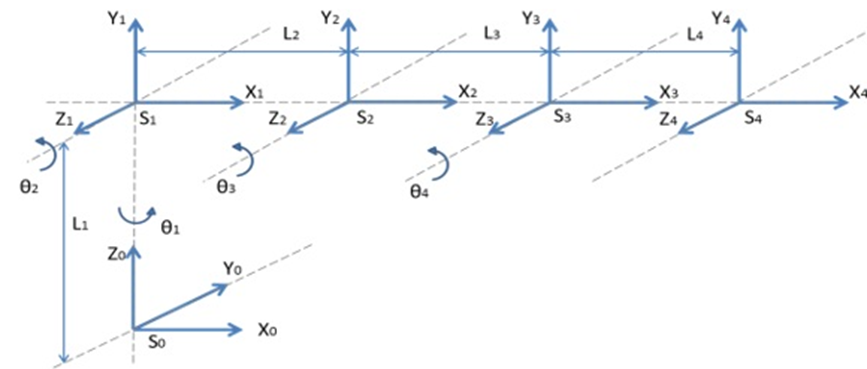

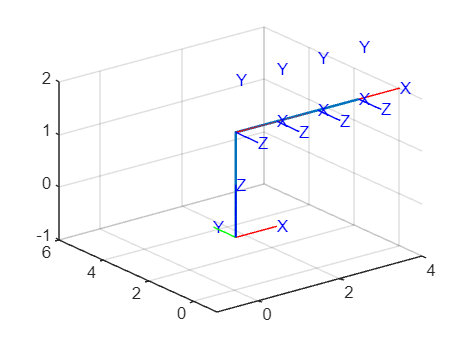

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%Rotx(90°) Tras(2)
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(rotz(0), [1 0 0]);
H3=SE3(rotz(0), [1 0 0]);
H4=SE3(rotz(0), [1 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;

%Coordenadas de la estructura de translación y rotación
x=[0 0 3 ];
y=[0 0 0 ];
z=[0 2 2 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])

 disp(H40)

    1         0         0         3
    0         0        -1         0
    0         1         0         2
    0         0         0         1


## **Segundo ejercicio**

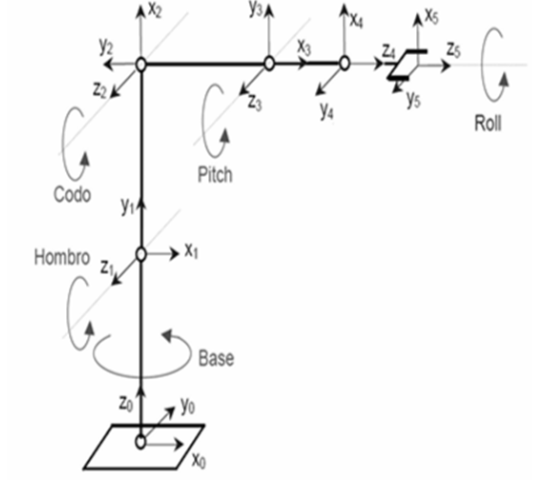

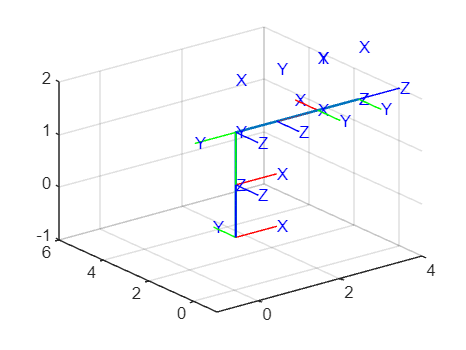

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%Rotx(90°) Tras(2)
H1=SE3(rotx(pi/2), [0 0 1]);
H2=SE3(rotz(pi/2), [0 1 0]);
H3=SE3(rotz(-pi/2),[0 -1 0]);
H4=SE3(roty(pi/2), [1 0 0]);
H5=SE3(rotz(pi/2), [0 0 0]);
H6=SE3(rotz(2*pi), [0 0 1]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;
H50= H40*H5;
H60= H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 0 3 ];
y=[0 0 0 ];
z=[0 2 2 ];
plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H40, H50,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H50, H60,'rgb','axis', [-1 4 -1 6 -1 2])

 disp(H60)

            0         0         1         3
    2.449e-16        -1         0         0
            1 2.449e-16         0         2
            0         0         0         1


## **Tercer ejercicio**

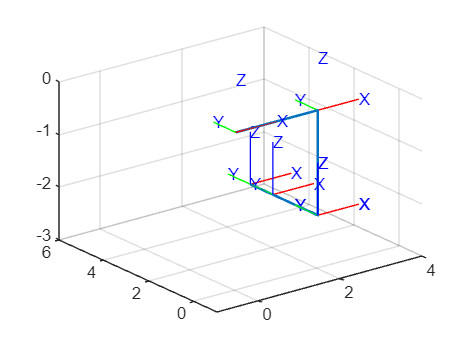

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%Rotx(90°) Tras(2)
H1=SE3(rotz(0), [2 0 0]);
H2=SE3(rotx(2*pi), [0 0 -2]);
H3=SE3(roty(2*pi), [0 0 0]);
H4=SE3(rotx(2*pi),[0 2 0]);
H5=SE3(roty(2*pi), [0 1 0]);


H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;
H50= H40*H5;

%Coordenadas de la estructura de translación y rotación

x=[0 2  2 2 2];
y=[0 0  0 2 3];
z=[0 0 -2 -2 -2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -3 0]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -3 0])
% %Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -3 0])
% % %Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -3 0])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -3 0])
%Realizamos una animación para la siguiente trama
 tranimate(H40, H50,'rgb','axis', [-1 4 -1 6 -3 0])

 disp(H50)

            1 5.999e-32-4.899e-16         2
      1.8e-31         1 4.899e-16         3
    4.899e-16-4.899e-16         1        -2
            0         0         0         1
